# Logistic Map Demonstration

## Cobweb plots

Simulate the logistic map for 20 steps with parameter $r=4$. Plot the result as a cobweb. (Note the use of an anonymous function).

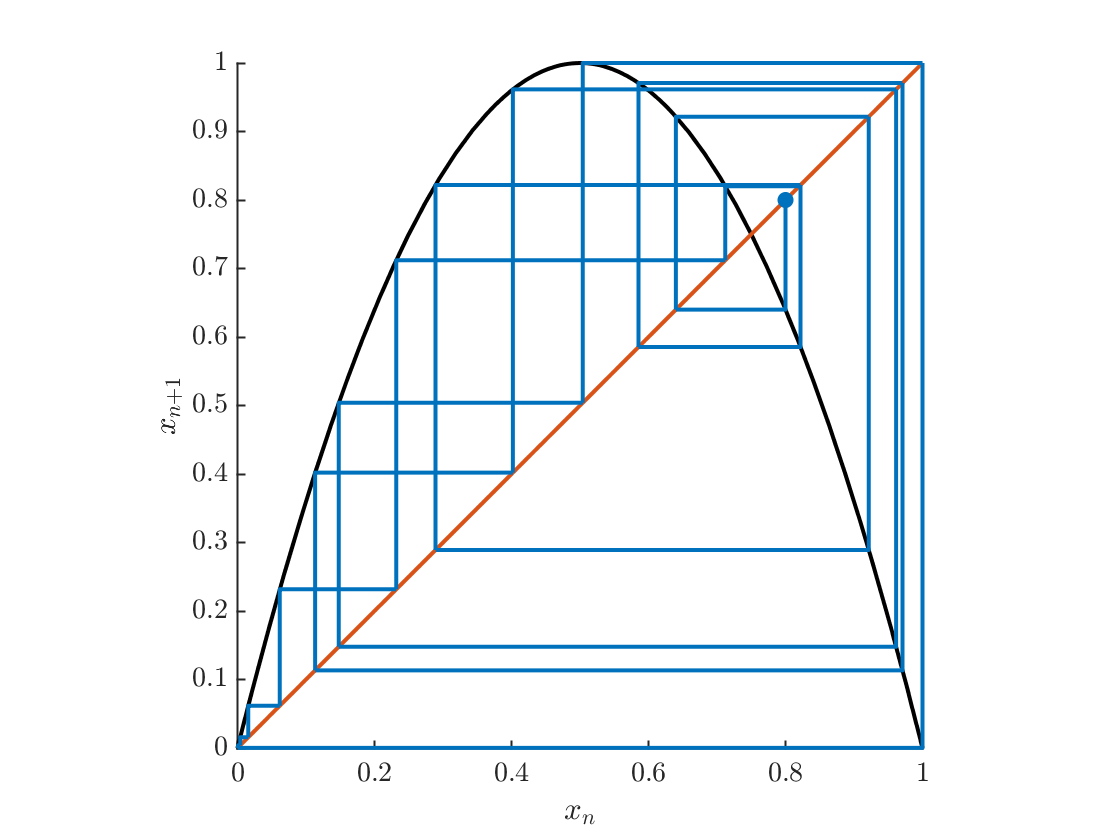

f=@(x)logisticMap(x,4);
pauseFlag=false;

N=20;
x0=0.8;
x=cobweb(f,[0 1],x0,N,pauseFlag);

Change the initial condition slightly to show that the trajectories eventually diverge.

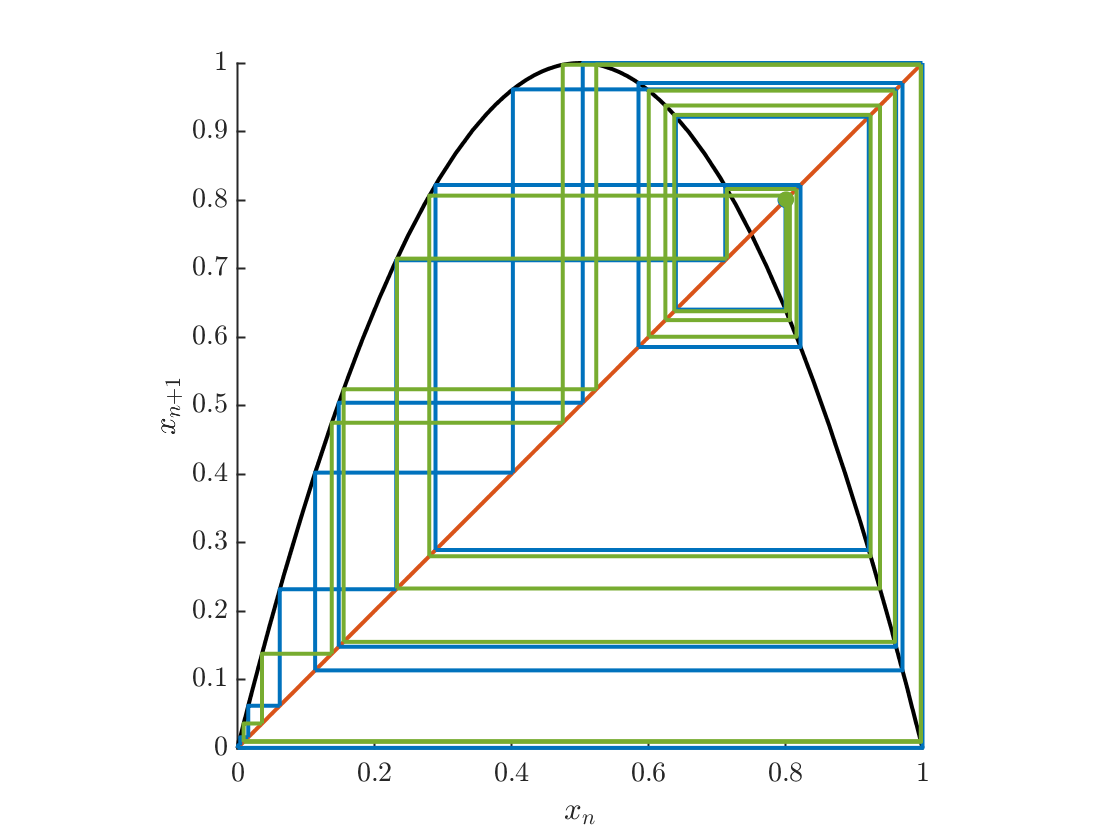

epsilon=.001;
x1=x0+epsilon;
xx=iterateMap(f,x1,N);cobwebLine(xx);

Now plot the two time series as functions of discrete time to see how they diverge exponentially.

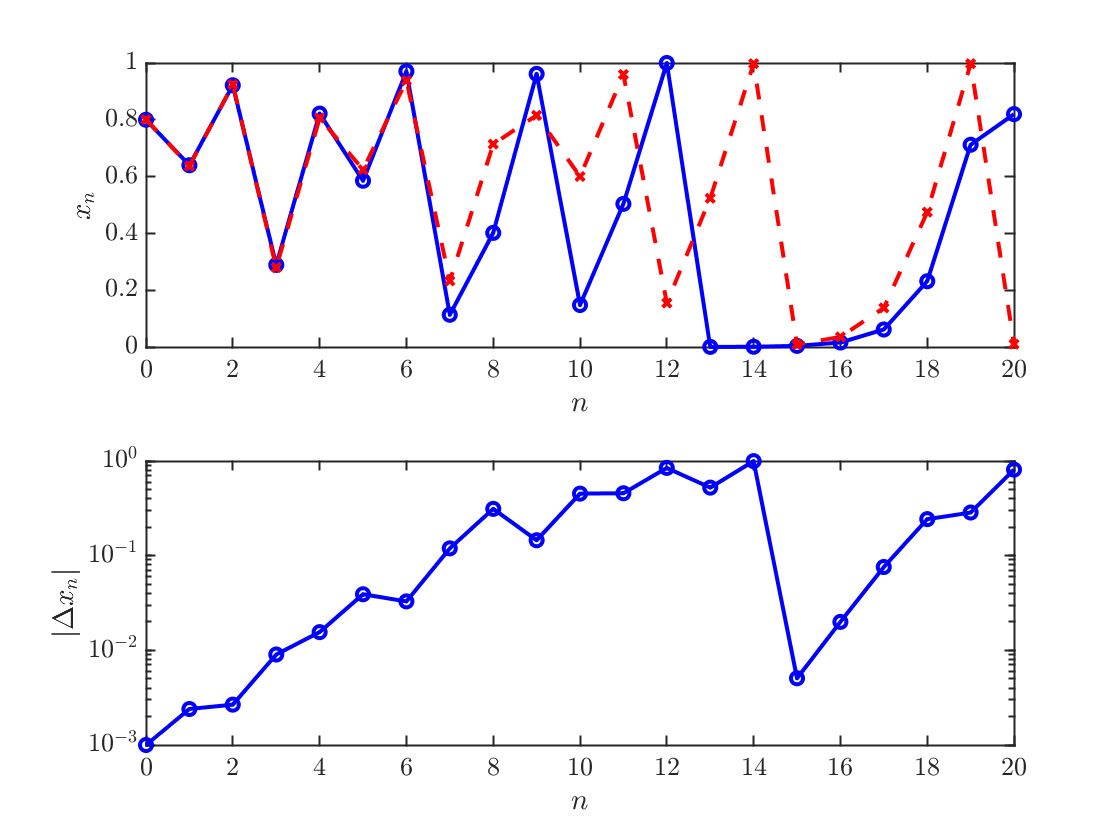

subplot(2,1,1); cla;
plot(0:N,x,'b-o');
hold on;
plot(0:N,xx,'r--x')
xlabel('$n$');ylabel('$x_n$')
subplot(2,1,2)
semilogy(0:N,abs(x-xx),'b-o')
xlabel('$n$');ylabel('$|\Delta x_n|$')

## Bifurcation diagram

Vary the parameter $r$. For each value of $r$, simulate for `N` steps. Discard the first `nTransient` iterates and record the rest. See a crude period-doubling diagram. Compute the Liapunov exponent, which will be used in the next plot.

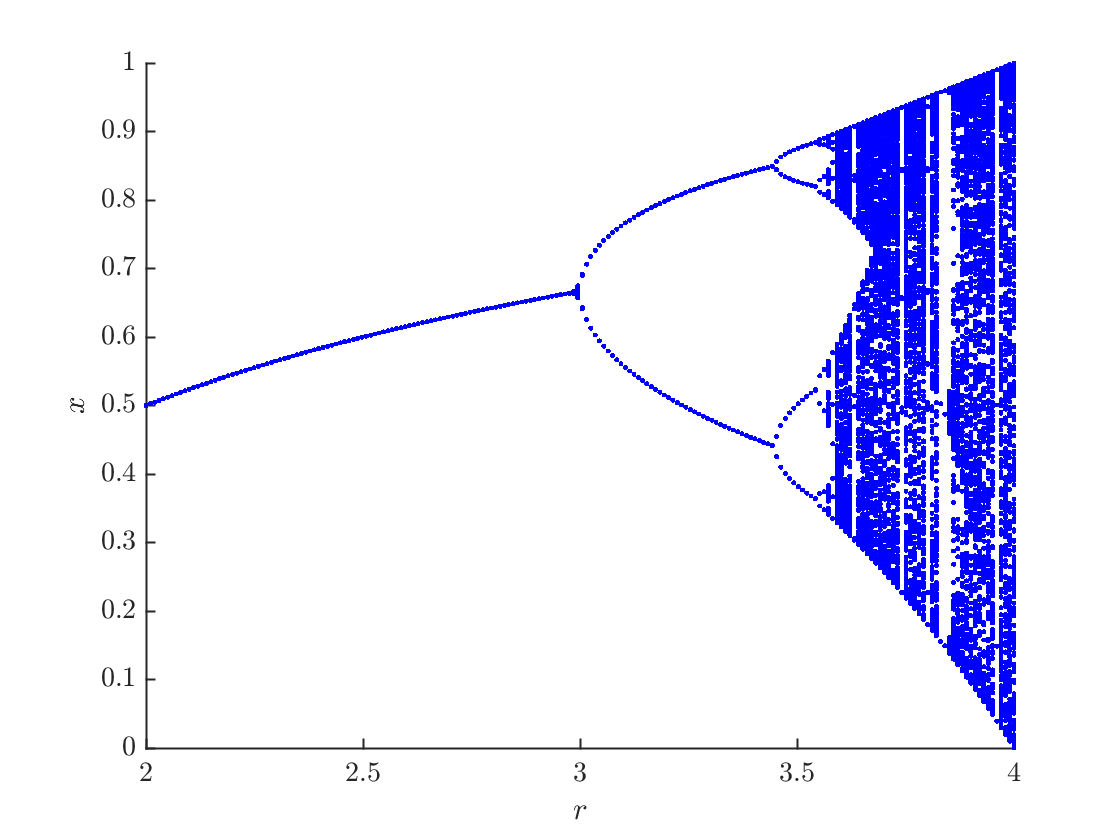

rMin=2; rMax=4;
nr=201; dr=(rMax-rMin)/nr;
N=500;
nTransient=200;
clf; hold on;
liapunovExp=zeros(nr+1,1);
for k=0:nr
    r=rMin+k*dr;
    f=@(x)logisticMap(x,r);
    fprime=@(x)logisticMapPrime(x,r);
    x=iterateMap(f,x0,N);
    plot(r*ones(N-nTransient),x(nTransient+1:N),'.','color','b')
    liapunovExp(k+1)=liapunov1D(fprime,x);
end
xlabel('$r$');ylabel('$x$')

## Plot the Liapunov exponent

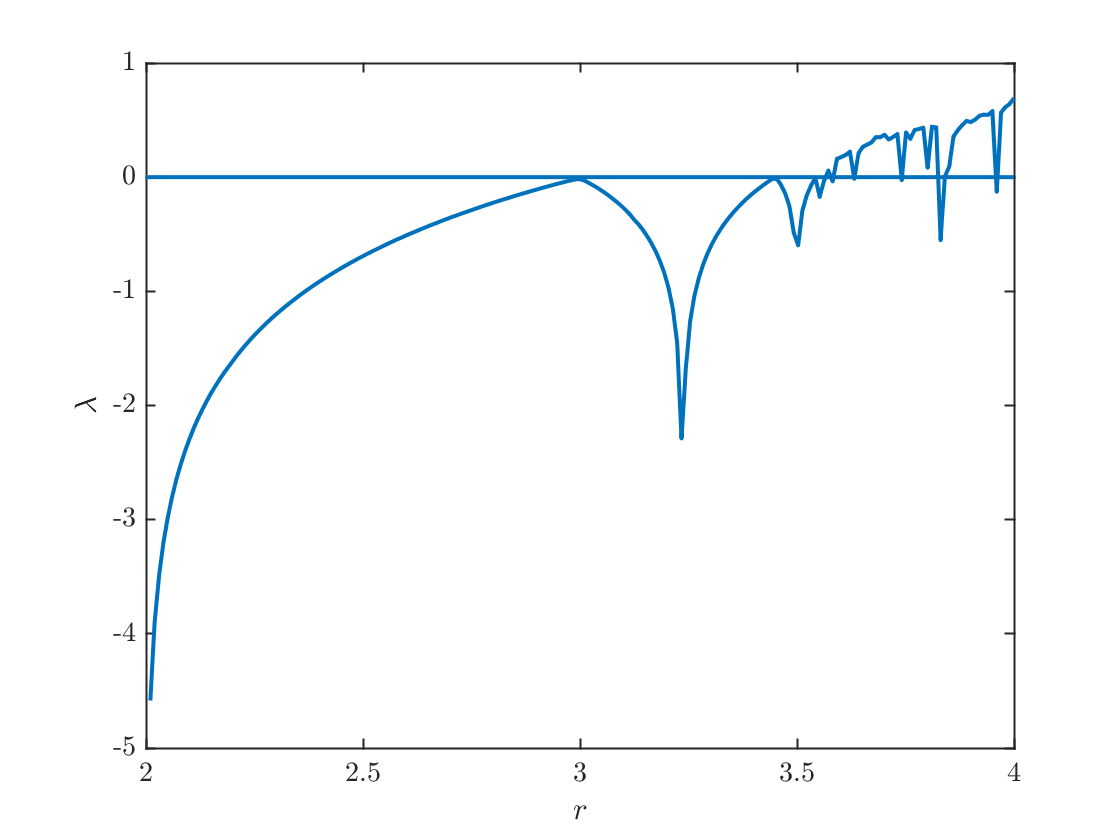

clf
plot(linspace(rMin,rMax,nr+1),liapunovExp)
refline(0,0)
xlabel('$r$');ylabel('$\lambda$')

# Universality

Strogatz tells us that for any map of the form $x_{n+1} = r f (x_n)$, where $f(x)$ is unimodal with a quadratic maximum, then the period doubling diagram will look essentially the same. (See the book for the technical details of this statement.)

Here we reproduce the last two figures with the map $x_{n+1} = r \sin{{(\pi x_n)}$

## Bifurcation diagram

Vary the parameter $r$. For each value of $r$, simulate for `N` steps. Discard the first `nTransient` iterates and record the rest. See a crude period-doubling diagram. Compute the Liapunov exponent, which will be used in the next plot.

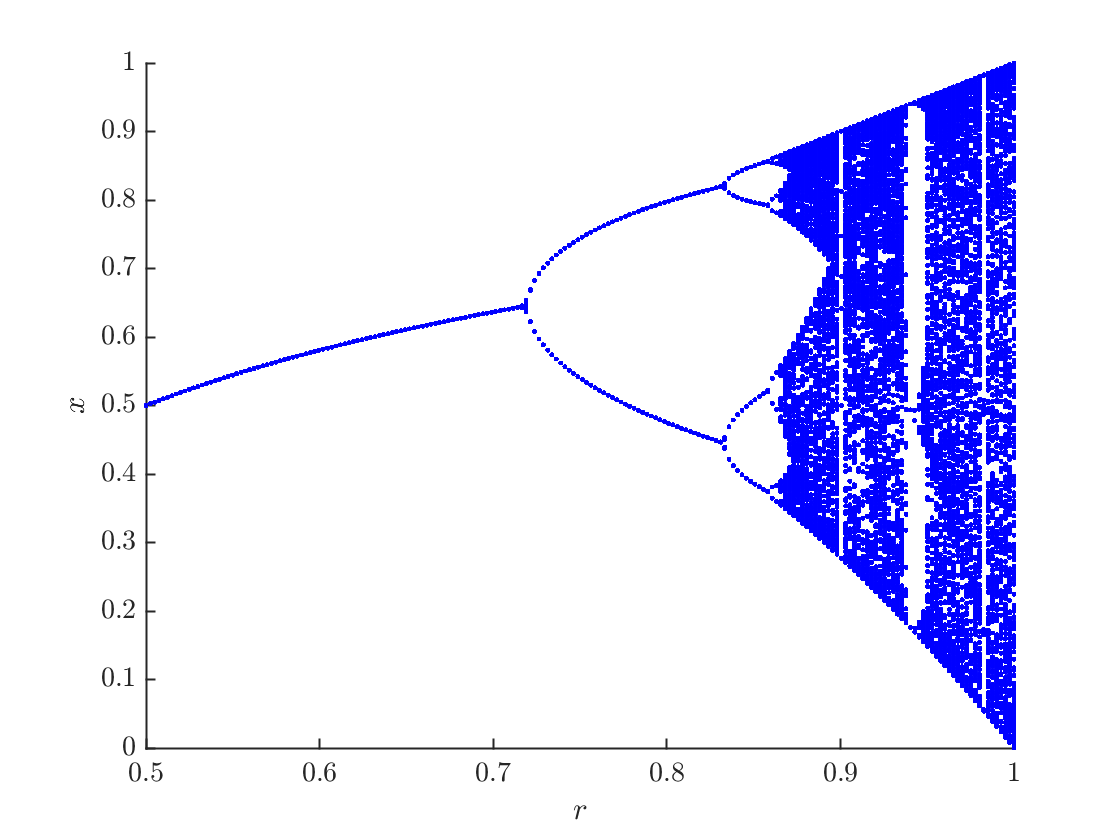

rMin=1/2; rMax=1;
nr=201; dr=(rMax-rMin)/nr;
N=500;
nTransient=200;
clf; hold on;
liapunovExp=zeros(nr+1,1);
for k=0:nr
    r=rMin+k*dr;
    f=@(x)sineMap(x,r);
    fprime=@(x)sineMapPrime(x,r);
    x=iterateMap(f,x0,N);
    plot(r*ones(N-nTransient),x(nTransient+1:N),'.','color','b')
    liapunovExp(k+1)=liapunov1D(fprime,x);
end
xlabel('$r$');ylabel('$x$')

## Plot the Liapunov exponent

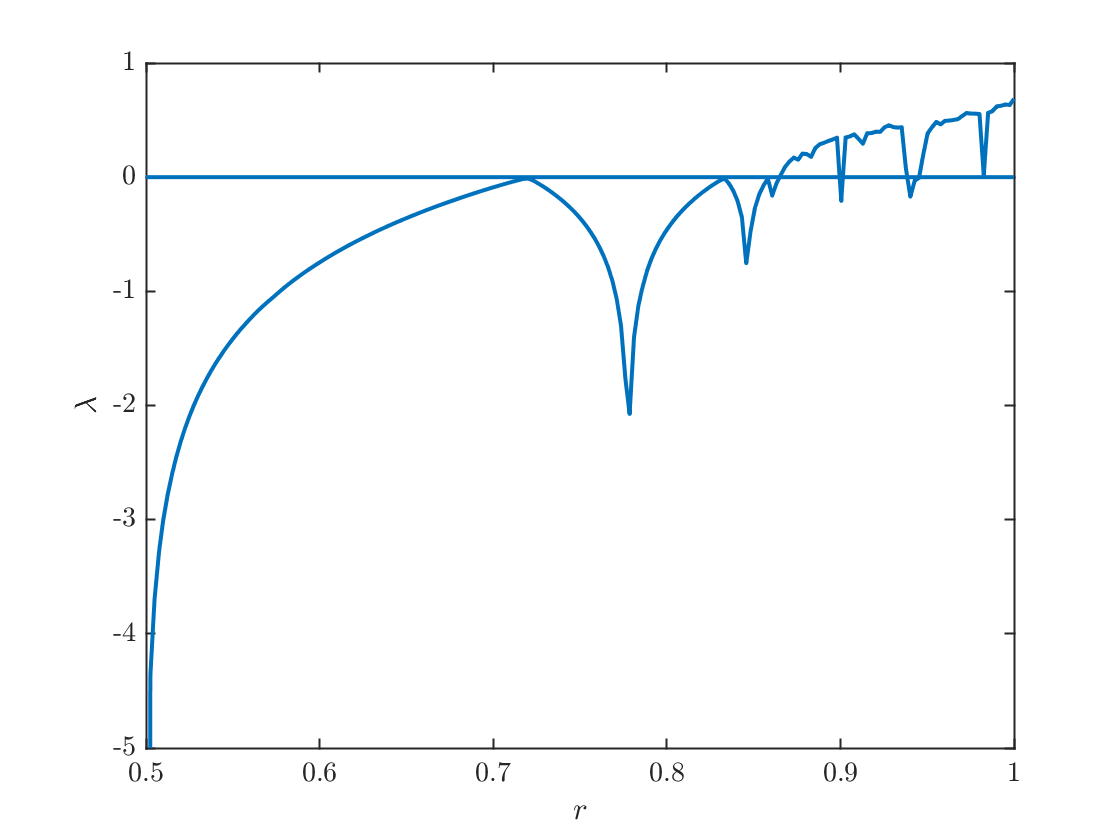

clf
plot(linspace(rMin,rMax,nr+1),liapunovExp)
refline(0,0)
xlabel('$r$');ylabel('$\lambda$')
set(gca,'ylim',[-5 1])

## Plot the $n$th-iterate of a map

The logistic map has period 3 windows for $r=3.835$

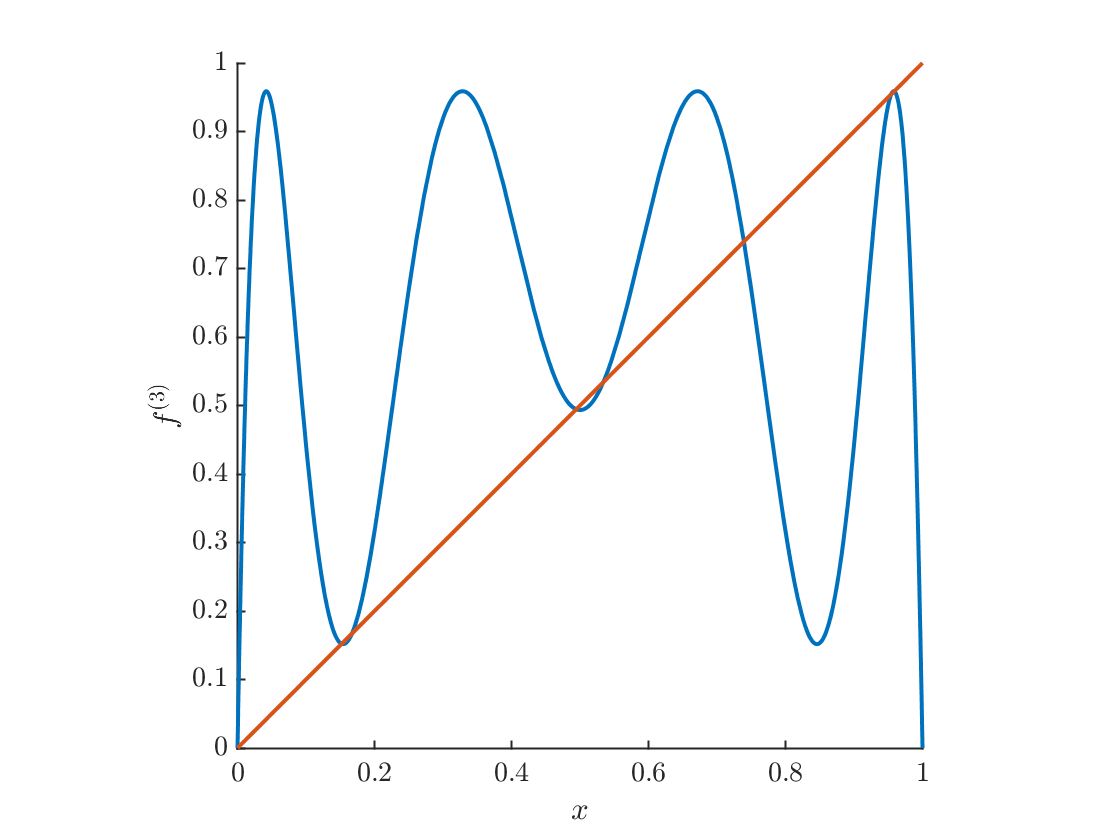

f=@(x)logisticMap(x,3.835); 
plotNthIterate(f,3,[0 1])
xlabel('$x$')
ylabel('$f^{(3)}$')

## Functions called

function y = logisticMap(x,r)
y= r*x.*(1-x);
end

function y = logisticMapPrime(x,r)
y = r*(1-2*x);
end

function y=sineMap(x,r)
y= r*sin(pi*x);
end

function y=sineMapPrime(x,r)
y = r*pi*cos(pi*x);
end